# ExtendedKalmanFilter

## Practice 1: [Stable System] Estimation of the Position and Uncertainty of a Pendulum in Air

### Propagation: nonlinear

### Correction: linear

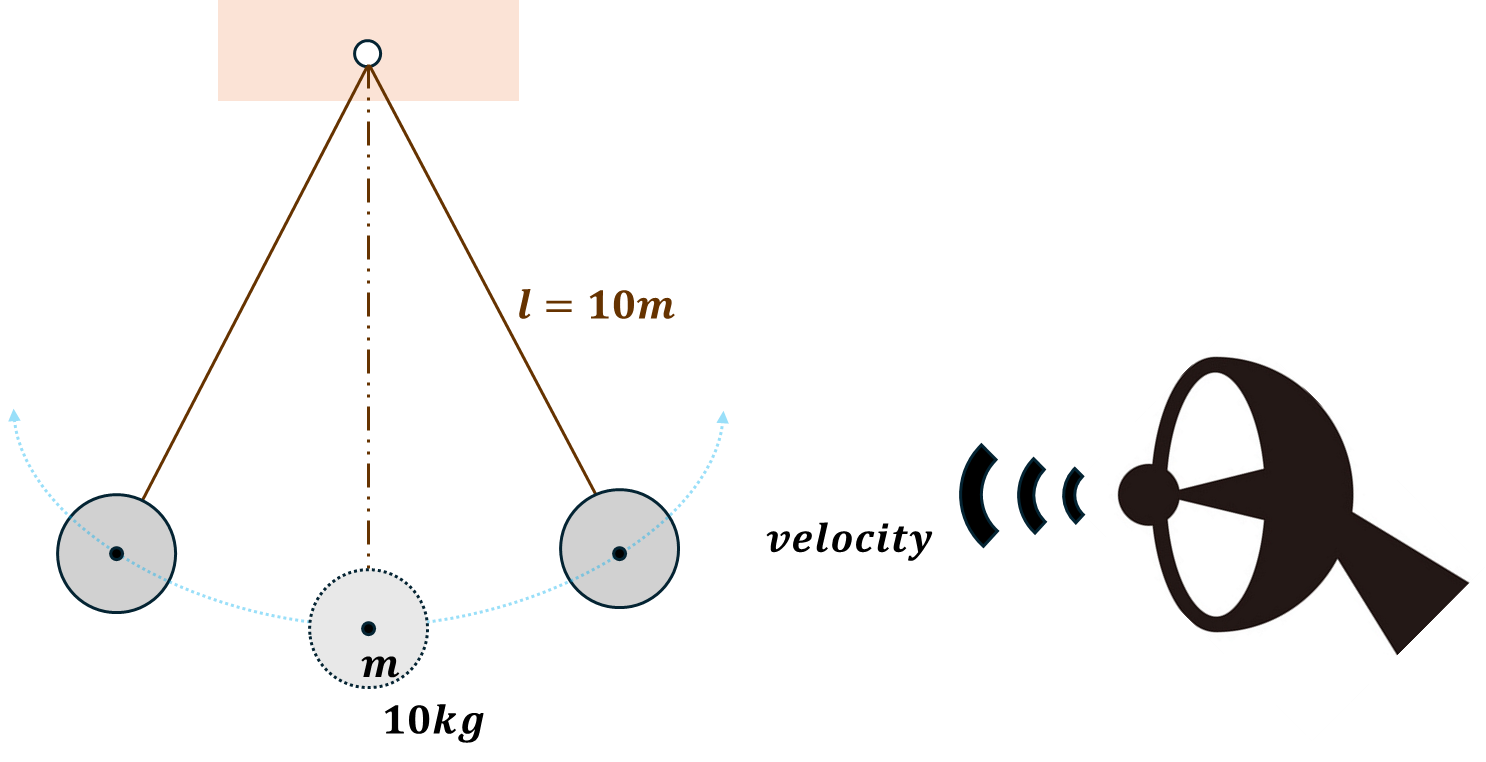

A pendulum is swinging in the air.

Due to air registance, the kinematic energy of the pendulum is being dissipated.

The pendulum has a **mass of 10 kg** and a **string length of 10 meters**.

**Estimate the position and velocity** of pendulum and **its uncertainty** over time.

The **initial position of the pendulum** follows a normal distribution **𝑁(45 deg,3 deg)**,

and the **initial velocity** follows a normal distribution **𝑁(20 deg/s,0.5 deg/s)**.

Assume that the **air resistance force** is proportional to the velocity with some constant damping coefficient, given by **F_air = 20 ⋅ 𝜔**,

and the **gravitational velocity** is **10 m/s^2**.

However, as the pendulum moved significantly, linearity at small angles could no longer be assumed.

We can measure** the velocity of pendulum** with radar system.

The algorithm's uncertainty follows the  a normal distribution with **standard deviation (σ) = 2 m/s**

### Motion Equation

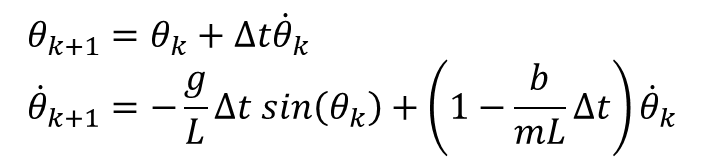

- **m **: mass

- **L **: string length

- **g **: gravitational velocity

- **b **: damping coefficient

- θ : estimated angle

### Measurement Equation

- : measured velocity

- : estimated velocity

### State space equation modeling

         

- : mean of the state vector x_k+1

- : mean of the state vector x_k

- : system matrix

- : control matrix

- : measurement of time k

- : measurement matrix

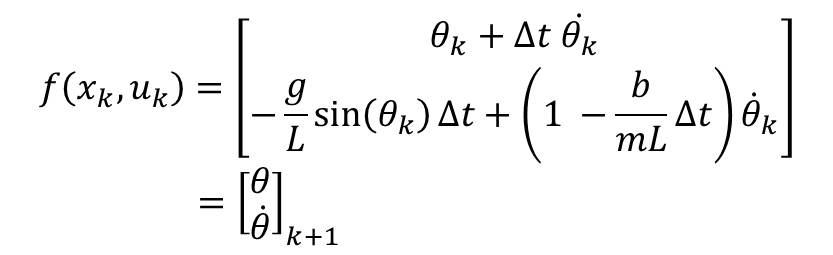

      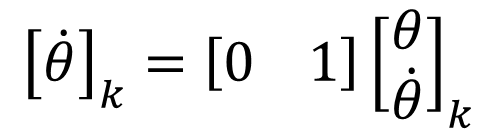

clear; close all;
% Set simulation time
total_time = 10;
dt = 0.02;
n_step = total_time / dt;
time = dt:dt:total_time;

% Physics
gravity = 10.0;
pen_length = 10.0;
pen_mass = 10.0;
air_damping = 20.0;

% State space equation modeling
num_of_state = 2;
num_of_measurement = 1;

% F matrix for compare extended kalman filter and normal kalman filter
F_kf = [1                      dt; ...
        -gravity/pen_length*dt (1-air_damping/(pen_mass*pen_length)*dt)];
H = [0 1];

% System's Pole
eigen_value = eig(F_kf);
disp("eigen value of system(F): ");

eigen value of system(F): 


disp(eigen_value);

   0.9980 + 0.0199i
   0.9980 - 0.0199i



### Estimate state and uncertainty with Kalman filter

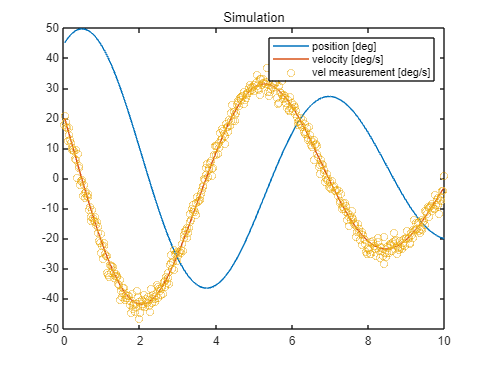

% Initialize state
X_init = [deg2rad(45);
          deg2rad(20)];
X_kf_pri = zeros(num_of_state, n_step);
X_kf_pri(:,1) = X_init;
X_kf_post = zeros(num_of_state, n_step);
X_kf_post(:,1) = X_init;
X_ekf_pri = zeros(num_of_state, n_step);
X_ekf_pri(:,1) = X_init;
X_ekf_post = zeros(num_of_state, n_step);
X_ekf_post(:,1) = X_init;

% Simulate true data
X_true = zeros(num_of_state, n_step);
X_true(:,1) = X_init;
for i = 2:n_step
    X_true(:,i) = [(X_true(1, i-1) + X_true(2, i-1) * dt) ;...
                   (-gravity/pen_length*dt*sin(X_true(1, i-1)) + (1- air_damping/(pen_mass*pen_length)*dt) * X_true(2,i-1))];
end
meas_radar_vel = normrnd(X_true(2,:), deg2rad(2.0));
figure;
plot(time, rad2deg(X_true(1,:)));
hold on;
plot(time, rad2deg(X_true(2,:)));
plot(time, rad2deg(meas_radar_vel), 'o');
title("Simulation");
legend("position [deg]", "velocity [deg/s]", "vel measurement [deg/s]");


%%%% TODO: Advanced %%%%: Change the initial state uncertainty (P_init)
% Initialize covariance of state
sigma_pose_init = 2.0;
sigma_vel_init = 4;
P_init = [deg2rad(sigma_pose_init)^2  0;
          0  deg2rad(sigma_vel_init)^2];
P_kf_pri = cell(n_step,1);
P_kf_pri{1} = P_init;
P_kf_post = cell(n_step,1);
P_kf_post{1} = P_init;
P_ekf_pri = cell(n_step,1);
P_ekf_pri{1} = P_init;
P_ekf_post = cell(n_step,1);
P_ekf_post{1} = P_init;

%%%% TODO: Advanced %%%%: Change the process noise (Q) and measurement noise (R)
% Process noise
sigma_process_pose = 1.0;
sigma_process_vel = 1.0;
Q = [(deg2rad(sigma_process_pose )* dt)^2  0;
     0     (deg2rad(sigma_process_vel)* dt)^2];
% Measurement noise
sigma_meas_vel = 1.0;
R = deg2rad(sigma_meas_vel)^2;

#### Propagation: Time update

 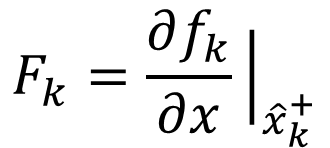    

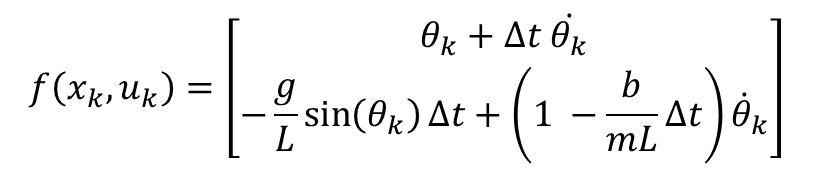

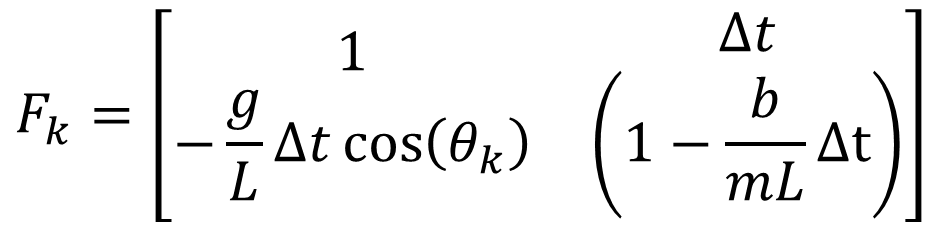

% Estimation
n_skip_update_frame = 10;
for i = 2:n_step    
    %%%% TODO %%%%: Fill the right equation
    % Propagation: Time update
    X_kf_pri(:,i) = F_kf*X_kf_post(:,i-1);
    P_kf_pri{i} = F_kf*P_kf_post{i-1}*F_kf' + Q;
    X_ekf_pri(:,i) = [X_kf_post(1,i-1)+dt*X_kf_post(2,i-1);
                      -gravity/pen_length*sin(X_kf_post(1,i-1))*dt+(1-air_damping/(pen_mass*pen_length)*dt)*X_kf_post(2,i-1)];
    F_ekf = [1 dt;
             -gravity/pen_length*dt*cos(X_kf_post(1,i-1)) (1-air_damping/(pen_mass*pen_length)*dt)];
    P_ekf_pri{i} = F_ekf*P_ekf_post{i-1}*F_ekf'+Q;

#### Correction: Measurement update

    if (rem(i, n_skip_update_frame) == 0) % limite update rate

error_rms_kf = 0.0373

        %%%% TODO %%%%: Fill the right equation

error_rms_ekf = 0.0373

        % Correction: Measurement update (measurement: meas_radar_vel)
        % Kalman Filter
        K_kf = P_kf_pri{i}*H'*(H*P_kf_pri{i}*H' + R)^-1;
        X_kf_post(:,i) = X_kf_pri(:,i) + K_kf*(meas_radar_vel(i) - H*X_kf_pri(:,i));
        P_kf_post{i} = (eye(num_of_state) - K_kf*H)*P_kf_pri{i}*(eye(num_of_state) - K_kf*H)' + K_kf*R*K_kf';
        
        % Extended Kalman Filter
        K_ekf = P_ekf_pri{i}*H'*(H*P_ekf_pri{i}*H'+R)^(-1);
        X_ekf_post(:,i) = X_ekf_pri(:,i)+K_ekf*(meas_radar_vel(i)-H*X_ekf_pri(:,i));
        P_ekf_post{i} = (eye(2)-K_ekf*H)*P_ekf_pri{i}*(eye(2)-K_ekf*H)'+K_ekf*R*K_ekf';
    else
        % Skip update: Don't edit this
        X_kf_post(:,i) = X_kf_pri(:,i);
        P_kf_post{i} = P_kf_pri{i};
        X_ekf_post(:,i) = X_ekf_pri(:,i);
        P_ekf_post{i} = P_ekf_pri{i};
    end
end

error_rms_kf = rms(X_kf_post(1, :) - X_true(1,:))
error_rms_ekf = rms(X_ekf_post(1,:) - X_true(1,:))

P_kf_mat = cell2mat(P_kf_post)';
std_position_x = (P_kf_mat(1, 1:2:end)).^(0.5);
std_velocity_x = (P_kf_mat(2, 2:2:end)).^(0.5);
P_ekf_mat = cell2mat(P_ekf_post)';
std_position_kalman_x = (P_ekf_mat(1, 1:2:end)).^(0.5);
std_velocity_kalman_x = (P_ekf_mat(2, 2:2:end)).^(0.5);

#### Visualization

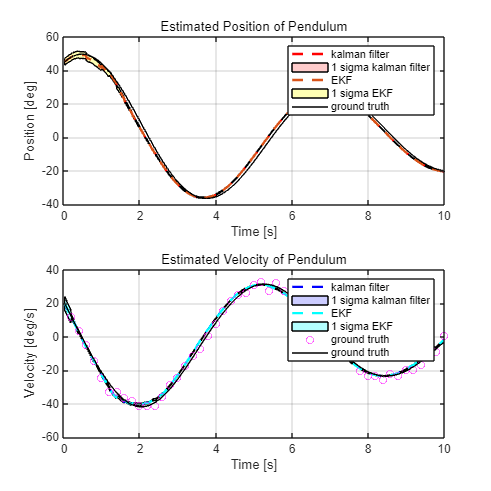

% Visualization
figure('Position', [100, 100, 900, 900]); % 가로 길이를 늘린 크기 설정

% Position plot
subplot(2,1,1);
position_upper_std = X_kf_post(1,:) + std_position_x;
position_lower_std = X_kf_post(1,:) - std_position_x;
position_uncertainty_x = [position_upper_std position_lower_std(end:-1:1)];
position_uncertainty_y = [time(1:n_step) time(n_step:-1:1)];
pt_p_u = fill(position_uncertainty_y, rad2deg(position_uncertainty_x), [1 0.8 0.8]);
hold on;

position_upper_kalman_std = X_ekf_post(1, :) + std_position_kalman_x;
position_lower_kalman_std = X_ekf_post(1, :) - std_position_kalman_x;
position_uncertainty_kalman_x = [position_upper_kalman_std position_lower_kalman_std(end:-1:1)];
position_uncertainty_kalman_y = [time(1:n_step) time(n_step:-1:1)];
pt_k_u = fill(position_uncertainty_kalman_y, rad2deg(position_uncertainty_kalman_x), [1.0 1.0 0.7]);

pt_p = plot(time, rad2deg(X_kf_post(1,:)), '--r', "LineWidth",2);
pt_k = plot(time, rad2deg(X_ekf_post(1,:)), '--', "LineWidth", 2);
pt_gt = plot(time, rad2deg(X_true(1,:)), '-k');
grid on;
xlabel('Time [s]');
ylabel('Position [deg]');
title('Estimated Position of Pendulum');
legend([pt_p, pt_p_u, pt_k, pt_k_u, pt_gt], ["kalman filter" "1 sigma kalman filter" "EKF" "1 sigma EKF" "ground truth"]);

% Velocity plot
subplot(2,1,2);
velocity_upper_std = X_kf_post(2,:) + std_velocity_x;
velocity_lower_std = X_kf_post(2,:) - std_velocity_x;
velocity_uncertainty_x = [velocity_upper_std velocity_lower_std(end:-1:1)];

velocity_uncertainty_y = [time(1:n_step) time(n_step:-1:1)];
pt_v_u = fill(velocity_uncertainty_y, rad2deg(velocity_uncertainty_x), [0.8 0.8 1.0]);
hold on;

velocity_upper_kalman_std = X_ekf_post(2,:) + std_velocity_kalman_x;
velocity_lower_kalman_std = X_ekf_post(2,:) - std_velocity_kalman_x;
velocity_uncertainty_kalman_x = [velocity_upper_kalman_std velocity_lower_kalman_std(end:-1:1)];
velocity_uncertainty_kalman_y = [time(1:n_step) time(n_step:-1:1)];
pt_v_k_u = fill(velocity_uncertainty_kalman_y, rad2deg(velocity_uncertainty_kalman_x), [0.7 1.0 1.0]);

pt_v = plot(time, rad2deg(X_kf_post(2,:)), '--b', "LineWidth",2);
pt_v_k = plot(time, rad2deg(X_ekf_post(2,:)), '--c', "LineWidth", 2);
pt_v_m = plot(time(n_skip_update_frame:n_skip_update_frame:end), rad2deg(meas_radar_vel(n_skip_update_frame:n_skip_update_frame:end)),'om');
pt_gt = plot(time, rad2deg(X_true(2,:)), 'k');
grid on;
xlabel('Time [s]');
ylabel('Velocity [deg/s]');
title('Estimated Velocity of Pendulum');
legend([pt_v, pt_v_u, pt_v_k, pt_v_k_u, pt_v_m, pt_gt], ["kalman filter" "1 sigma kalman filter" "EKF" "1 sigma EKF" "ground truth" "ground truth"]);

#### Animation

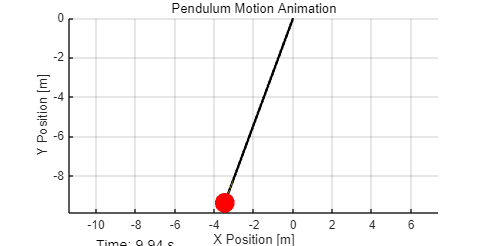

% Animation of the pendulum
figure('Position', [100, 100, 1200, 600]);
axis equal;
hold on;
grid on;
xlabel('X Position [m]');
ylabel('Y Position [m]');
title('Pendulum Motion Animation');

% Calculate pendulum position
theta = X_ekf_post(1, :);
string_length = 10;
pendulum_radius = 0.5;
x_pendulum = string_length * sin(theta);
y_pendulum = -string_length * cos(theta);

% Initialize pendulum line and pendulum circle
pendulum_line = line([0 x_pendulum(1)], [0 y_pendulum(1)], 'Color', 'k', 'LineWidth', 2);

% Initialize uncertainty arc
uncertainty_angle_range = linspace(-1, 1, 100);
uncertainty_arc = plot(0, 0, 'y', 'LineWidth', 40);
set(uncertainty_arc, 'Color', [1, 1, 0, 0.6]);

pendulum_circle = rectangle('Position', [x_pendulum(1) - pendulum_radius, y_pendulum(1) - pendulum_radius, ...
                                          2 * pendulum_radius, 2 * pendulum_radius], ...
                            'Curvature', [1, 1], 'FaceColor', 'r', 'EdgeColor', 'none');


time_text = text(-string_length, -string_length - 1.5, sprintf('Time: %.2f s', time(1)), 'FontSize', 12);

% Animation loop
for k = 2:5:n_step
    set(pendulum_line, 'XData', [0 x_pendulum(k)], 'YData', [0 y_pendulum(k)]);
    set(pendulum_circle, 'Position', [x_pendulum(k) - pendulum_radius, y_pendulum(k) - pendulum_radius, ...
                                      2 * pendulum_radius, 2 * pendulum_radius]);
    angle_uncertainty = std_position_x(k) / string_length; % Angle uncertainty in radians
    uncertainty_arc_x = string_length * sin(theta(k) + angle_uncertainty * uncertainty_angle_range);
    uncertainty_arc_y = string_length * -cos(theta(k) + angle_uncertainty * uncertainty_angle_range);
    set(uncertainty_arc, 'XData', uncertainty_arc_x, 'YData', uncertainty_arc_y);

    set(time_text, 'String', sprintf('Time: %.2f s', time(k)));

    drawnow;
    pause(0.02);
end


## Practice 2: [Unstable System] Estimation of the Position and Uncertainty of Vehicle with Dead Reckoning

### Propagation: nonlinear

### Correction: nonlinear

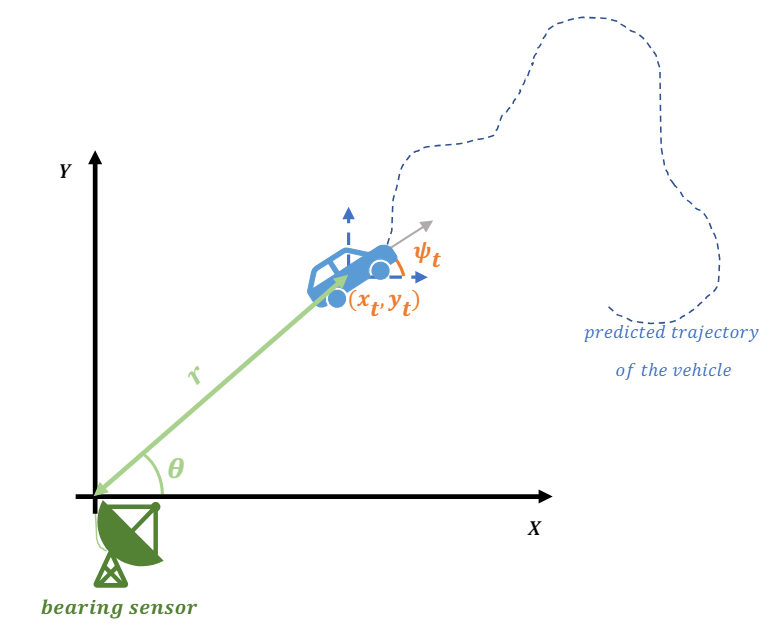

A vehicle is moving on a 2D plane. The initial conditions for the vehicle's state are given as follows:

- **Initial position 𝑥** follows a normal distribution **𝑁(0 m,1 m).**

- **Initial position 𝑦** follows a normal distribution **𝑁(0 m,1 m).**

- **Initial velocity 𝑣𝑥** follows a normal distribution **𝑁(4 m/s,1 m/s).**

- **Initial velocity 𝑣𝑦** follows a normal distribution **𝑁(2 m/s,1 m/s).**

We measure the vehicle's position with** Radar system.**

The Radar measurement are given as follows:

- Position measurement **z **follows a normal distribution ***N(range,1.0) (m).***

Estimate the motion of the vehicle over time and plot the position and covariance on the 2D plane.

#### Simulation data

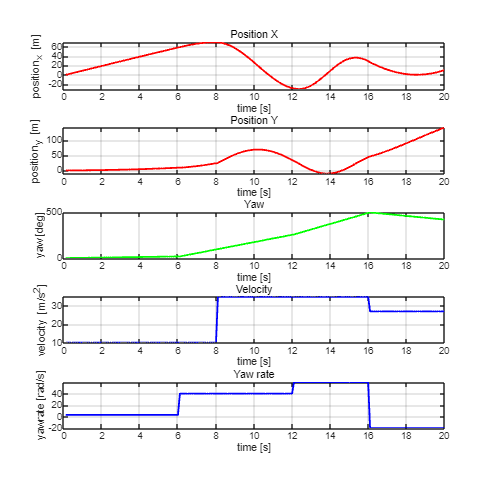

clear; close all;
% Example data for acceleration_x and acceleration_y
dt = 0.1;
total_time = 20;
n_step = total_time / dt;
time = dt:dt:total_time;

num_of_state = 3; % x, y, yaw
num_of_input = 2; % velocity, yawrate
num_of_measurement_order = 1; % range

% Initial conditions
initial_position_x = 0;
initial_position_y = 0;
initial_yaw_rad = deg2rad(0);

initial_velocity = 10;
initial_yaw_rate_degs = 3;

% Input generation
velocity = [initial_velocity*ones(1, (total_time*0.4)/dt), 35*ones(1, (total_time*0.4)/dt), 27*ones(1, (total_time*0.2)/dt)];
yawrate_rads = deg2rad([initial_yaw_rate_degs*ones(1, (total_time*0.3)/dt), 40*ones(1, (total_time*0.3)/dt), 60*ones(1, (total_time*0.2)/dt), -20*ones(1, (total_time*0.2)/dt)]);
input = [velocity;...
         yawrate_rads];

% Integrate velocity to get velocity and position
X_true = zeros([num_of_state, n_step]);
X_true(:,1) = [initial_position_x;...
               initial_position_y;...
               initial_yaw_rad];
for i = 2:n_step
    X_true(:, i) = [(X_true(1,i-1) + input(1,i-1)*dt*cos(X_true(3,i-1)));...
                    (X_true(2,i-1) + input(1,i-1)*dt*sin(X_true(3,i-1)));...
                    (X_true(3,i-1) + input(2,i-1)*dt)];
end

% Measurement generation
radar_meas_range_noise_sigma = 1.0;
radar_meas_update_interval = 2;
radar_range = sqrt(X_true(1,:).^2 + X_true(2,:).^2);
radar_meas = normrnd(radar_range, radar_meas_range_noise_sigma);

% Plot the data
figure('Position', [100, 100, 900, 900]); % 가로 길이를 늘린 크기 설정

% Plot the position data
subplot(5, 1, 1);
plot(time, X_true(1,:), 'LineWidth', 1.5, 'Color', "r");
xlabel('time [s]');
ylabel('position_x [m]');
title('Position X');
grid on;

subplot(5, 1, 2);
plot(time, X_true(2,:), 'LineWidth', 1.5, 'Color', "r");
xlabel('time [s]');
ylabel('position_y [m]');
title('Position Y');
grid on;

subplot(5, 1, 3);
plot(time, rad2deg(X_true(3,:)), 'LineWidth', 1.5, 'Color', "g");
xlabel('time [s]');
ylabel('yaw [deg]');
title('Yaw');
grid on;

% Plot the velocity data
subplot(5, 1, 4);
plot(time, velocity, 'LineWidth', 1.5, 'Color', "b");
xlabel('time [s]');
ylabel('velocity [m/s^2]');
title('Velocity');
grid on;

subplot(5, 1, 5);

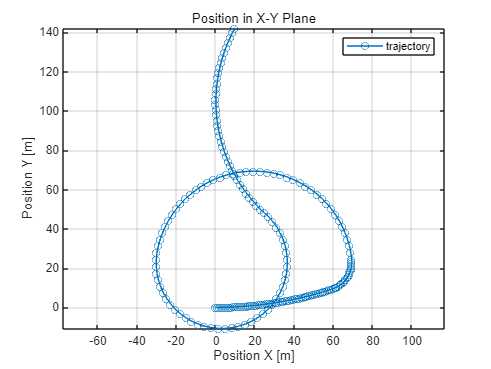

plot(time, rad2deg(yawrate_rads), 'LineWidth', 1.5, 'Color', "b");
xlabel('time [s]');
ylabel('yawrate [rad/s]');
title('Yaw rate');
grid on;


% Plot the trajectory in x-y plane
figure;
plot(X_true(1,:), X_true(2,:), '-o');
xlabel('Position X [m]');

ylabel('Position Y [m]');
title('Position in X-Y Plane');
legend("trajectory");
grid on;
axis equal;

#### Motion Equation

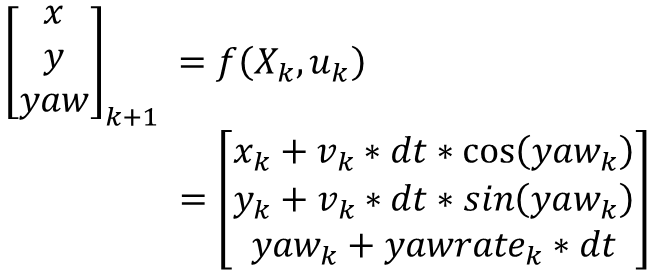

- x_t , y_t : vehicle's X and Y **position** at t

- v_t : vehicle's **velocity** at t

- yaw_t: vehicle's **heading** at t

- dT: **sampling time**

**Measurement Equation**

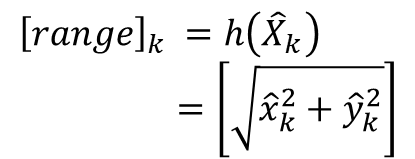

-       : estimated position x at t

-      : estimated position y at t

- range_t        : radar range measurement at t

### State space equation modeling

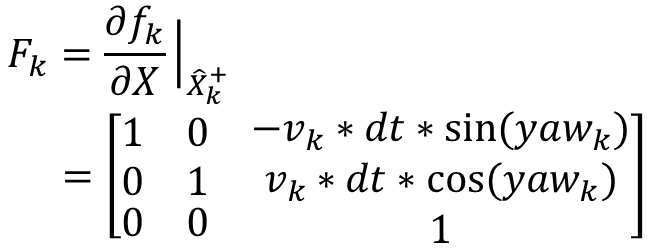

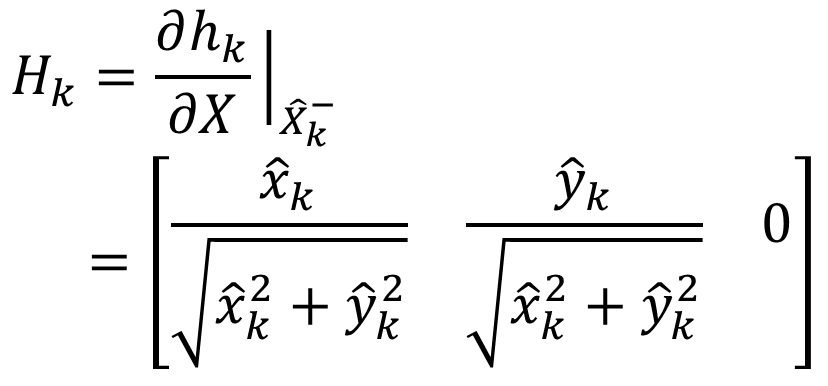

### Estiate state and unceratinty with Kalman Filter

% Initialization state
X_init = [initial_position_x;
          initial_position_y;
          initial_yaw_rad];
X_ekf_pri = zeros(num_of_state, n_step);
X_ekf_pri(:,1) = X_init;
X_ekf_post = zeros(num_of_state, n_step);
X_ekf_post(:,1) = X_init;

% Initialize uncertainty
P_init = [10 0 0; ...
         0 10 0; ...
         0 0 0.5];
P_ekf_pri = cell(n_step,1);
P_ekf_pri{1} = P_init;
P_ekf_post = cell(n_step,1);
P_ekf_post{1} = P_init;

%%%% TODO: Advanced %%%%: Change the process noise and measurement noise
% Determine the process and measruement noise
Q_pose = (1*dt)^2;
Q_vel = (1*dt)^2;
Q_yaw = (0.1*dt)^2;
Q = diag([Q_pose, Q_pose, Q_yaw]);

R_range = 1.0^2;
R_theta = (deg2rad(3.0))^2;
R = diag(R_range);

#### Propagation: Time update

% Estimation
for i = 2:n_step    
    %%%% TODO %%%%: Fill the right equation
    X_ekf_pri(:,i) = [X_ekf_post(1,i-1)+velocity(i-1)*dt*cos(X_ekf_post(3,i-1));
                      X_ekf_post(2,i-1)+velocity(i-1)*dt*sin(X_ekf_post(3,i-1));
                      X_ekf_post(3,i-1)+yawrate_rads(i-1)*dt];
    F_ekf = [1 0 -velocity(i-1)*dt*sin(X_ekf_post(3,i-1));
             0 1 velocity(i-1)*dt*cos(X_ekf_post(3,i-1));
             0 0 1];
    P_ekf_pri{i} = F_ekf*P_ekf_post{i-1}*F_ekf'+Q;

#### Correction: Measurement update

        

    if ( rem(i, radar_meas_update_interval) == 0) % limite update rate
        %%%% TODO %%%%: Fill the right equation
        % Correction: Measurement update (measurement: meas_radar_vel)
        H = [X_ekf_pri(1,i)/sqrt(X_ekf_pri(1,i)^2+X_ekf_pri(2,i)^2) X_ekf_pri(2,i)/sqrt(X_ekf_pri(1,i)^2+X_ekf_pri(2,i)^2) 0];
        K = P_ekf_pri{i}*H'*(H*P_ekf_pri{i}*H'+R)^(-1);
        X_ekf_post(:,i) = X_ekf_pri(:,i)+K*(radar_meas(i)-H*X_ekf_pri(:,i));
        P_ekf_post{i} = (eye(3)-K*H)*P_ekf_pri{i}*(eye(3)-K*H)'+K*R*K';
    else
        % Skip update
        X_ekf_post(:,i) = X_ekf_pri(:,i);
        P_ekf_post{i} = P_ekf_pri{i};
    end
end

P_ekf_mat = cell2mat(P_ekf_post)';
std_position_kalman_x = (P_ekf_mat(1, 1:num_of_state:end)).^(0.5);
std_position_kalman_y = (P_ekf_mat(2, 2:num_of_state:end)).^(0.5);
std_yaw_kalman = (P_ekf_mat(3, 3:num_of_state:end)).^(0.5);

#### Visualization

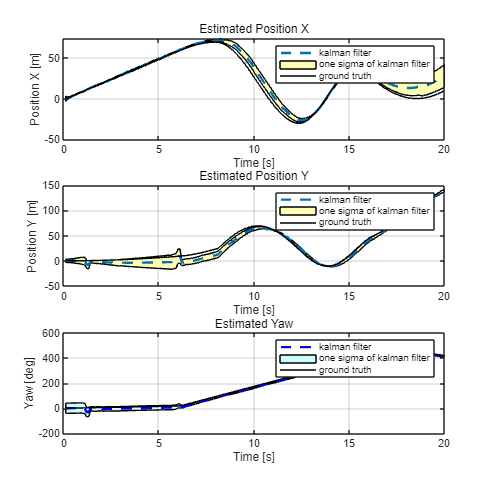

% Visualization for X and Y
figure('Position', [100, 100, 900, 900]);

% Position plot for X
subplot(3,1,1);
p_kalman_upper_std_x = X_ekf_post(1, :) + std_position_kalman_x;
p_kalman_lower_std_x = X_ekf_post(1, :) - std_position_kalman_x;
p_kalman_uncertainty_x = [p_kalman_upper_std_x p_kalman_lower_std_x(end:-1:1)];
p_kalman_uncertainty_time_x = [time(1:n_step) time(n_step:-1:1)];
pt_p_k_u_x = fill(p_kalman_uncertainty_time_x, p_kalman_uncertainty_x, [1 1 0.7]);
hold on;

pt_p_k_x = plot(time, X_ekf_post(1,:), '--', "LineWidth", 2);
pt_p_gt_x = plot(time, X_true(1,:), '-k');
grid on;
xlabel('Time [s]');
ylabel('Position X [m]');
title('Estimated Position X');
legend([pt_p_k_x, pt_p_k_u_x, pt_p_gt_x], ["kalman filter" "one sigma of kalman filter" "ground truth"]);

% Position plot for Y
subplot(3,1,2);
p_kalman_upper_std_y = X_ekf_post(2, :) + std_position_kalman_y;
p_kalman_lower_std_y = X_ekf_post(2, :) - std_position_kalman_y;
p_kalman_uncertainty_y = [p_kalman_upper_std_y p_kalman_lower_std_y(end:-1:1)];
p_kalman_uncertainty_time_y = [time(1:n_step) time(n_step:-1:1)];
pt_p_k_u_y = fill(p_kalman_uncertainty_time_y, p_kalman_uncertainty_y, [1 1 0.7]);
hold on;

pt_p_k_y = plot(time, X_ekf_post(2,:), '--', "LineWidth", 2);
pt_p_gt_y = plot(time, X_true(2,:), '-k');
grid on;
xlabel('Time [s]');
ylabel('Position Y [m]');
title('Estimated Position Y');
legend([pt_p_k_y, pt_p_k_u_y, pt_p_gt_y], ["kalman filter" "one sigma of kalman filter" "ground truth"]);


% Velocity plot for Y
subplot(3,1,3);
velocity_k_upper_std_y = rad2deg(X_ekf_post(3,:) + std_yaw_kalman);
velocity_k_lower_std_y = rad2deg(X_ekf_post(3,:) - std_yaw_kalman);

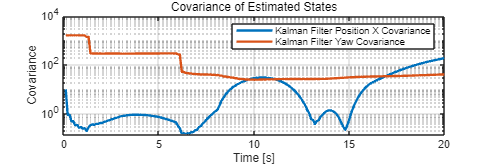

velocity_uncertainty_y = [velocity_k_upper_std_y velocity_k_lower_std_y(end:-1:1)];
velocity_k_uncertainty_time_y = [time(1:n_step) time(n_step:-1:1)];
pt_v_k_u_y = fill(velocity_k_uncertainty_time_y, velocity_uncertainty_y, [0.8 1.0 1.0]);
hold on;

pt_v_k_y = plot(time, rad2deg(X_ekf_post(3,:)), '-- b', "LineWidth", 2);
pt_v_gt_y = plot(time, rad2deg(X_true(3,:)), '-k');
grid on;
xlabel('Time [s]');
ylabel('Yaw [deg]');
title('Estimated Yaw');

legend([pt_v_k_y, pt_v_k_u_y, pt_v_gt_y], ["kalman filter" "one sigma of kalman filter" "ground truth"]);

% Covariance plot for position, velocity, and velocity
figure('Position', [100, 100, 900, 300]);
semilogy(time, std_position_kalman_x.^2, '-', 'LineWidth', 2);
hold on;
semilogy(time, rad2deg(std_yaw_kalman).^2, '-', 'LineWidth', 2);
grid on;
xlabel('Time [s]');
ylabel('Covariance');
title('Covariance of Estimated States');
legend("Kalman Filter Position X Covariance", "Kalman Filter Yaw Covariance");

#### Animation

% X-Y plane position plot with covariance (1 sigma)
figure('Position', [100, 100, 900, 900]);
hold on;

h_ellipse = plot_covariance_ellipse([X_ekf_post(1,1); X_ekf_post(2,1)], P_ekf_post{1}(1:2, 1:2), 'r', 'yellow');
h_trajectory = plot(X_ekf_post(1,1), X_ekf_post(2,1), 'b--', "LineWidth", 2); % past trajectory
h_traj_gt = plot(X_true(1), X_true(2), '-k');
h_position = plot(X_ekf_post(1,1), X_ekf_post(2,1), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
diff_x = input(1,1) * cos(X_ekf_post(3,1));
diff_y = input(1,1) * sin(X_ekf_post(3,1));
h_heading = quiver(X_ekf_post(1,1), X_ekf_post(2,1), diff_x, diff_y, 'g', 'LineWidth', 2, 'MaxHeadSize', 2); % velocity arrow
dir_ang = atan2(X_ekf_post(2,1), X_ekf_post(1,1));
dir_x = cos(dir_ang);
dir_y = sin(dir_ang);
h_gnss_meas = quiver(X_ekf_post(1,1), X_ekf_post(2,1), radar_meas(1)*dir_x,radar_meas(1)*dir_y, 'b', 'LineWidth', 2, 'MaxHeadSize', 2);
time_text = text(max(X_ekf_post(1,:)) + 10, max(X_ekf_post(2,:)) - 10, sprintf('Time: %.2f s', time(1)), 'FontSize', 12);

legend([h_ellipse h_heading h_gnss_meas], ["pose uncertainty" "velocity" "range measurement"]);

xlabel('Position X [m]');
ylabel('Position Y [m]');
title('Position in X-Y Plane with Covariance Ellipse');
grid on;
axis equal;
xlim([min(X_true(1,:)) - 20, max(X_true(1,:)) + 20]);
ylim([min(X_true(2,:)) - 20, max(X_true(2,:)) + 20]);

for i = 1:n_step
    delete(h_ellipse);

    h_ellipse = plot_covariance_ellipse([X_ekf_post(1,i); X_ekf_post(2,i)], P_ekf_post{i}(1:2, 1:2), 'r', 'yellow');
    set(h_trajectory, 'XData', X_ekf_post(1,i), 'YData', X_ekf_post(2,i));
    set(h_traj_gt, 'XData', X_true(1,:), 'YData', X_true(2,:));
    set(h_position, 'XData', X_ekf_post(1,i), 'YData', X_ekf_post(2,i));
    diff_x = input(1,i) * cos(X_ekf_post(3,i));
    diff_y = input(1,i) * sin(X_ekf_post(3,i));
    set(h_heading, 'XData', X_ekf_post(1,i), 'YData', X_ekf_post(2,i), 'UData', diff_x, 'VData', diff_y);
    

    meas_idx = (1:radar_meas_update_interval:i);
    dir_ang = atan2(X_ekf_post(2,i), X_ekf_post(1,i));
    dir_x = cos(dir_ang);
    dir_y = sin(dir_ang);
    set(h_gnss_meas, 'XData', 0, 'YData', 0, 'UData', radar_meas(meas_idx(end))*dir_x, 'VData', radar_meas(meas_idx(end))*dir_y);
    set(time_text, 'String', sprintf('Time: %.2f s', time(i)));
    
    drawnow;
    pause(0.01);
end

% Function to plot covariance ellipse

function h = plot_covariance_ellipse(mu, cov_matrix, edge_color, fill_color)
    [eigvec, eigval] = eig(cov_matrix);
    chisquare_val = 2.2789; % Corresponds to 1-sigma for 2 DOF
    theta_grid = linspace(0, 2*pi);
    phi = atan2(eigvec(2,1), eigvec(1,1));
    X0 = mu(1);
    Y0 = mu(2);
    a = chisquare_val*sqrt(eigval(1,1));
    b = chisquare_val*sqrt(eigval(2,2));
    ellipse_x_r  = a*cos(theta_grid);
    ellipse_y_r  = b*sin(theta_grid);
    R = [cos(phi) sin(phi); -sin(phi) cos(phi)];
    r_ellipse = [ellipse_x_r; ellipse_y_r]' * R;
    h = fill(r_ellipse(:,1) + X0, r_ellipse(:,2) + Y0, fill_color, 'EdgeColor', edge_color, 'FaceAlpha', 0.5);
end
